### **Force calibration**

% Data fit
xdata = forcedata.Force;
ydata = forcedata.Measurement;

fun = @(x,xdata)x(1)*xdata + x(2);

x0 = [1000,1000];
w_f = lsqcurvefit(fun,x0,xdata,ydata)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w_f = 	1.0e+03 *

    1.4546    5.0052


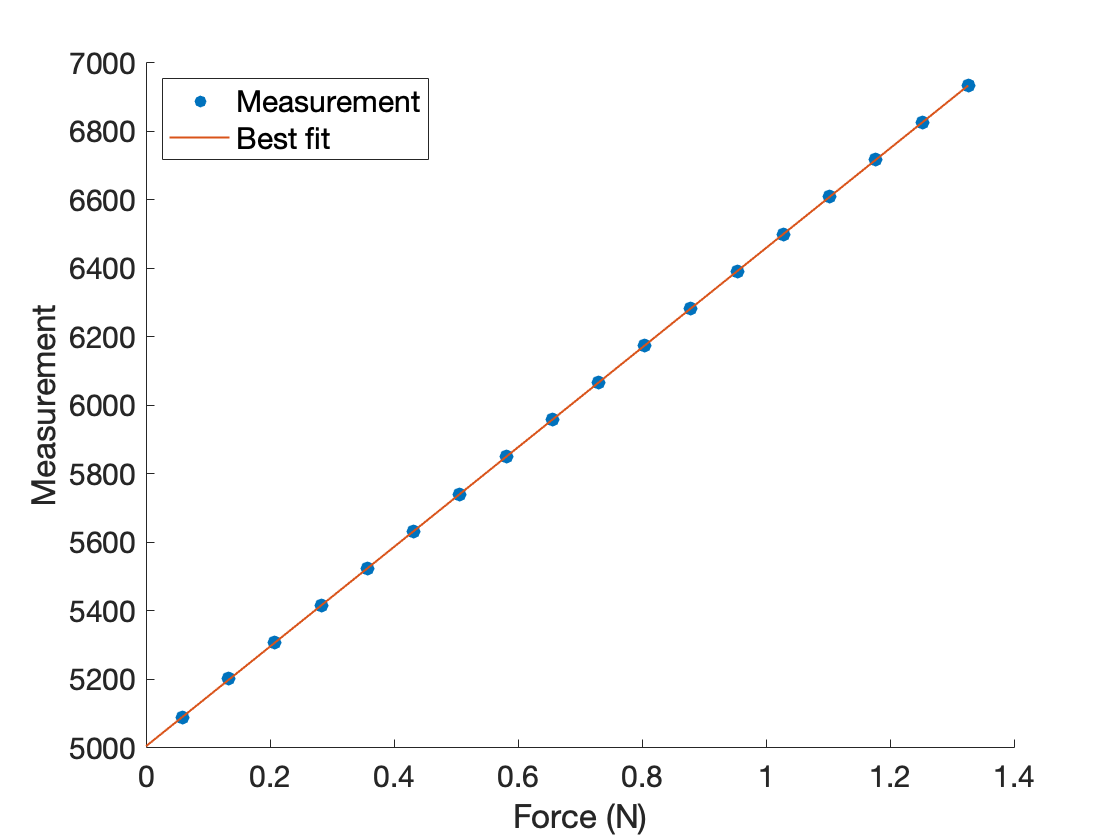

% plot best fit
figure
hold on;
scatter(forcedata.Force, forcedata.Measurement,50,'filled', "DisplayName", "Measurement");
xpoints = linspace(0,xdata(end),100);
ypoints = w_f(1)*xpoints + w_f(2);
plot(xpoints, ypoints, "DisplayName", "Best fit",'LineWidth',1);
xlabel("Force (N)", 'Fontsize', 15)
ylabel("Measurement",'Fontsize', 15)

ax = gca;
ax.YAxis.FontSize = 15;
ax.XAxis.FontSize = 15;
legend('Fontsize',15,'Location','northwest');
hold off;

### Distance calibration

% Data fit

% For first measurement 
% x_dist = distdata1.Distance;
% y_dist_light = distdata1.Measurement1; 
% y_dist_dark = distdata1.Measurement2;

% For second measurement 
x_dist = distdata2.Distance;
y_dist = distdata2.Measurement;

% Using a inverse power law
% x0 = [100,100,1];
% w_d_l = lsqcurvefit(@F_dist,x0,x_dist,y_dist_light);
% w_d_d = lsqcurvefit(@F_dist,x0,x_dist,y_dist_dark);

% Using a exponential law
x0 = [100,100,1];
w_dist = lsqcurvefit(@F_dist_exp,x0,x_dist,y_dist);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


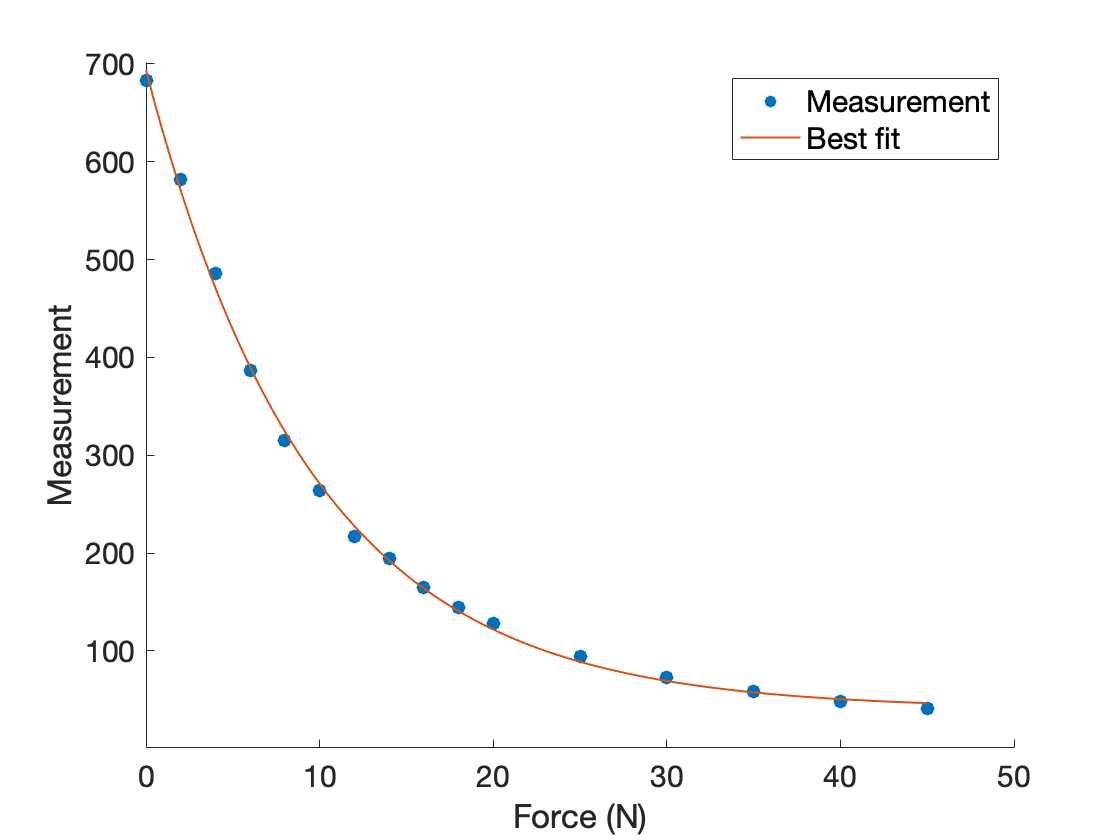

% plot best fit
% figure
% hold on;
% title("Distance sensor calibration: Light room");
% scatter(x_dist, y_dist_light, "DisplayName", "Measurement");
% xpoints = linspace(x_dist(1),x_dist(end),100);
% ypoints = F_dist(w_d_l, xpoints);
% plot(xpoints, ypoints, "DisplayName", "Best fit");
% hold off;
% 
% figure
% hold on;
% title("Distance sensor calibration: Dark room");
% scatter(x_dist, y_dist_dark, "DisplayName", "Measurement");
% xpoints = linspace(x_dist(1),x_dist(end),100);
% ypoints = F_dist(w_d_d, xpoints);
% plot(xpoints, ypoints, "DisplayName", "Best fit");
% hold off;
% 
% disp(w_d_l);
% disp(w_d_d);



% plot best fit
figure
hold on;
scatter(x_dist, y_dist, 50,'filled', "DisplayName", "Measurement");
xpoints = linspace(x_dist(1),x_dist(end),100);
ypoints = F_dist_exp(w_dist, xpoints);
plot(xpoints, ypoints, "DisplayName", "Best fit",'LineWidth',1);
xlabel("Force (N)", 'Fontsize', 15)
ylabel("Measurement",'Fontsize', 15)

ax = gca;
ax.YAxis.FontSize = 15;
ax.XAxis.FontSize = 15;
legend('Fontsize',15,'Location','northeast');
hold off;

disp(w_dist);

  652.6714   40.6702    6.6557



function F = F_dist(x,xdata)

    % convert x into 1/x^2
    for i = 1:numel(xdata)
        xdata(i) = 1/((xdata(i)^x(3)));
    end
    
    F = x(1)*xdata + x(2);
end

function F = F_dist_exp(x,xdata)

    % convert x into 1/x^2
    for i = 1:numel(xdata)
        xdata(i) = power(0.5, xdata(i)/x(3));
    end
    
    F = x(1)*xdata + x(2);
end